close all
clear all
clc
beep off

use_stationary_reference_frame = 1;

### PWM frequency and runtime for main task control

fPWM_AFE = 8e3; % AFE PWM frequency 
fPWM_INV = fPWM_AFE; % INVERTER PWM frequency
tPWM_INV = 1/fPWM_INV;
tPWM_AFE = 1/fPWM_AFE;
timeshift_pwm_carry = 0;
delayAFE_modB= timeshift_pwm_carry * fPWM_AFE*2*pi;
delayINV_modB= timeshift_pwm_carry * fPWM_INV*2*pi;
delayAFE_modA=0;
delayINV_modA=0;
dead_time=0 %6e-6; % IGBT dead-time (or blanking time)

dead_time =      0


s=tf('s');
ts_afe = 1/fPWM_AFE/2; % Sampling time of the control AFE as well as INVERTER
ts_inv = 1/fPWM_INV/2; % Sampling time of the control AFE as well as INVERTER
ts_spd = ts_inv/8;
z_inv=tf('z',ts_inv);
z_afe=tf('z',ts_afe);
z_spd=tf('z',ts_spd);

### PWM END SCALE current and DClink voltage 

Imax_adc=1049.835;
CurrentQuantization = Imax_adc/2^11;
Vdc_ref = 750; % DClink voltage reference
Vdc_nom = Vdc_ref; % DClink voltage reference

k_unbalance = 0.0;
k_factor = 1;
time_cm_disturbance = 4;
magnitude_disturbance = 0;
pw_disturbance = 1e-1;
k_sharing = 0.5;
iq_lim = 1.8;
CTRPIFF_CLIP_RELEASE = 0.05;
tz_threshold = 0;
Rprecharge=1; % Resistance of the DClink pre-charge circuit
start_torque_control = 0.2;
start_load_ramp = 8;
fault_time = 5;

simulation_torque_load = 0.5;
simulation_motor_speed = 1;
iq_ref_norm = 1; %for generator mode

im_param_calc_1

I0 =    199


1LE5603-3AC83-4AQ2-Z 
Values with label "bez" mean always peak 
Ubez means voltage peak phase 
 
Inom =  465.00000000 A 
Vnom =  400.00000000 V 
Ibez =  657.60930650 A 
Ubez =  326.59863237 V 
rpm =  1000.00000000 rpm 
freq_nom =  50.00000000 Hz 
rpm_load =  992.00000000 rpm 
polepairs =  3.00000000  
Rs =  0.00243233 Ohm 
Ls =  0.00369400 H 
Rr =  0.00469440 Ohm 
Lr =  0.00369400 H 
Lm =  0.00359169 H 
Im =  199.00000000 A 
Im_bez =  281.42849891 A 
Torque =  2426.57193039 kNm 
cosphi =  0.81000000  
eff =  0.95800000  
ucc =  400.00000000 V 
icc =  3589.00000000 A 
fcc =  50.00000000 Hz 


normalization
omega_sign = 1;
flip_phase = 0;

kz=1;

### Simulation data sampling time

tc=ts_inv/100;
ts=tc;
Omega_sim = no_load_rpm/60*2*pi * simulation_motor_speed;
sign_speed = 1;

wref = Omega_sim;
% Tload = Tnom;
Tload = Tnom * simulation_torque_load;

tref = 2; % ramp for speed
timeRamp = tref/tref; % ramp for load
simlength = 6;
t_misura = simlength;
Nc = ceil(t_misura/tc);
Ns_afe = ceil(t_misura/ts_afe);
Ns_inv = ceil(t_misura/ts_inv);

### DClink capacitor dimensioning

CFi=930e-6*8;

### MV/LV transformer

P = 1.1e6;
Vline = 400;
VphaseAFE=Vline/sqrt(3);
w_grid=50*2*pi;
Inom_trafo=P/Vline/sqrt(3);
Ld2= VphaseAFE/(100/5.7)/Inom_trafo/(w_grid)

Ld2 =      2.639078329087428e-05

Rd2 = 0.02*P/3/Inom_trafo^2

Rd2 =    0.002909090909091

### generator side inductance

LFi_d = 80e-6;
RLFi_d=157*0.08*LFi_d;
LFi_0 = 5e-6;
RLFi_0=RLFi_d/3;

### zero sequency current loop control

ki_0 = 2;
kp_0 = 0.1;


### Luenberger Observer

Aso = [1 ts_inv; 0 1];
Cso = [1 0];
p2place = exp([-200 -1000]*ts_inv);
Kobs = (acker(Aso',Cso',p2place))';
kg = Kobs(1)

kg =    0.073009136692643

kw = Kobs(2)

kw =   12.041968339133291

## speed control

kp_w=1;
ki_w=35;

### current control - iq

ki_inv_q = 18;
kp_inv_q = 0.5;

### current control - id

ki_inv_d = 18;
kp_inv_d = 0.5;

### lowpassfilter fst order

wcut2 = 2*pi*5;
lowpassfilter_fst = 10^(0/20)*1/(s/wcut2+1);
[num2, den2] = tfdata(lowpassfilter_fst,'v');
[A2, B2, C2, D2] = tf2ss(num2, den2);
Ad2 = exp(A2*ts_inv);
Hd2 = inv(A2)*((Ad2-1)*B2);
lowpassfilter_fst_d = ss(Ad2,Hd2,C2,D2,ts_inv);
% figure;
% set(cstprefs.tbxprefs,'FrequencyUnits','Hz');
% bode(lowpassfilter_fst_d);
% title('low pass fst order filter');
% grid;

## lowpassfilter fst order

wcut3 = 2*pi*161;
lowpassfilter_fst_hf = 10^(0/20)*1/(s/wcut3+1);
[num3, den3] = tfdata(lowpassfilter_fst_hf,'v');
[A3, B3, C3, D3] = tf2ss(num3, den3);
Ad3 = exp(A3*ts_inv);
Hd3 = inv(A3)*((Ad3-1)*B3);
lowpassfilter_fst_hf_d = ss(Ad3,Hd3,C3,D3,ts_inv);
% figure;
% set(cstprefs.tbxprefs,'FrequencyUnits','Hz');
% bode(lowpassfilter_fst_hf_d);
% title('low pass hf  filter');
% grid;

### lowpassfilter snd order

wcut4 = 2*pi*10;
lowpassfilter_snd = 10^(0/20)*1/(s/wcut4+1)^2;
lowpassfilter_snd_d = c2d(lowpassfilter_snd,ts_inv);
% figure;
% set(cstprefs.tbxprefs,'FrequencyUnits','Hz');
% bode(lowpassfilter_snd_d);
% title('low pass snd order ref filter');
% grid;

### igbt parameters

Ron = 1.75e-3;
Vgamma = 2.0;
Csnubber=0.15e-6;
Rsnubber=2.2;

% close all

### Inverter and IM faults generation settings

time_psm_phase_fault_inverter = 2e3;
time_psm_phase_resume_inverter = time_psm_phase_fault_inverter + 0.005;

time_leg_firing_fault_inverter = 2e3;
time_leg_firing_resume_inverter = time_leg_firing_fault_inverter + 0.002;

time_phase_cable_fault_inverter = 2e3;
time_phase_cable_resume_inverter = time_phase_cable_fault_inverter + 0.002;
R_phase_cable_fault_inverter = 1e3;

time_leg_firing_fault_afe = 2e3;
time_leg_firing_resume_afe = time_leg_firing_fault_afe + 0.002;

time_dclink_inverter_fault_inverter = 2e3;
time_dclink_inverter_resume_inverter = time_dclink_inverter_fault_inverter + 0.2;

time_pwm_fault_afe = 2e3;
time_pwm_resume_afe = time_pwm_fault_afe + tPWM_AFE;

time_pwm_fault_inverter = 2e3;
time_pwm_resume_inverter = time_pwm_fault_inverter + 2*tPWM_AFE;

time_ptp_realignment_fault = 2e3;
time_ptp_realignment_resume = time_ptp_realignment_fault + 0.005;


### Vector U/f control selection

use_vector_control = 1;
use_uf_control = 0

use_uf_control =      0

uf_uq_ref = 400*sqrt(2)/Vdc_ref;
% uf_uq_ref = 1;
uf_omega_ref = 1;

broken_bar_factor = 1;
im_motor_factor = 1;
speed_m_error_factor = 1;

### Double Integrator Observer for IM

Arso_im = [0 1; 0 0];
Crso_im = [1 0];
omega_rso_im = 2*pi*50;
polesrso_im = [-10 -40]*omega_rso_im;
Lrso_im = acker(Arso_im',Crso_im',polesrso_im)';
Adrso_im = eye(2) + Arso_im*ts_inv;
polesdrso_im = exp(ts_inv*polesrso_im);
Ldrso_im = acker(Adrso_im',Crso_im',polesdrso_im)'

Ldrso_im = 1.0e+03 *

   0.000722336914200
   1.551882449674950


% pll_i1_im = 80;
% pll_p_im = 1;

### IM Full State Observer based on Kalman Filter

omega_im_base = 2*pi*fnom;

J_norm = 1;
mu = 3/2*cp*Lm_norm/J_norm/Lr_norm;
alpha = Rr_norm/Lr_norm;
sigma = Ls_norm*(1-Lm_norm^2/Lr_norm/Ls_norm);
beta = Lm_norm/sigma/Lr_norm;
gamma = Rs_norm/sigma + beta*alpha*Lm_norm;
A_tilde = [-gamma 0 beta*alpha beta*omega_im_base; ...
          0 -gamma -beta*omega_im_base beta*alpha; ...
          alpha*Lm_norm 0 -alpha -omega_im_base; ...
          0 alpha*Lm_norm omega_im_base -alpha];
B_tilde = [1/sigma 0; 0 1/sigma; 0 0; 0 0];
C = [1 0 0 0; 0 1 0 0];

Ad = eye(4)+A_tilde*ts_inv;
Bd = B_tilde*ts_inv;

Qkalman = [1 0 0 0; 0 1 0 0; 0 0 ts_inv 0; 0 0 0 ts_inv]*100;
Rkalman = eye(2);

emf_fb_p = 0.2;
emf_p = emf_fb_p*4/10;



## C-Caller Settings

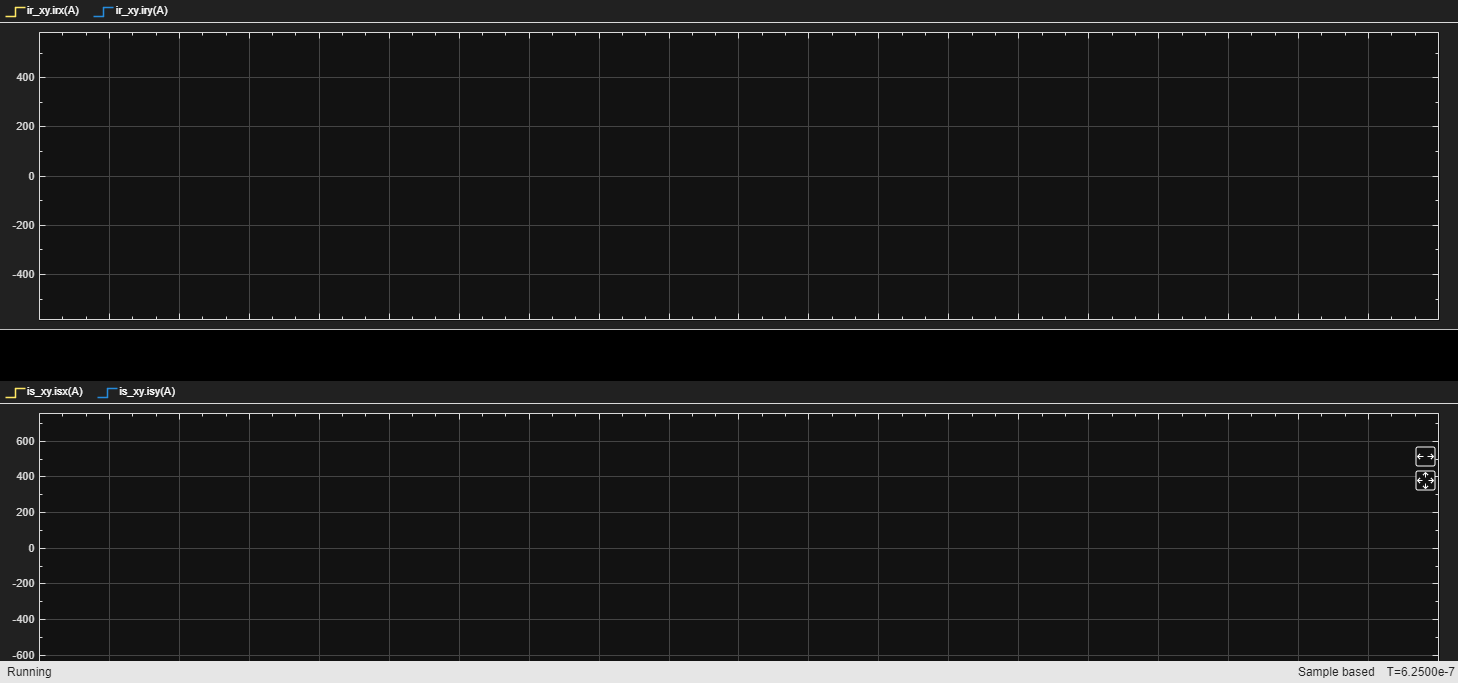

model = 'im_inv_sensorless_ctrl_model';
open_system(model);

Simulink.importExternalCTypes(model, 'Names', {'mavgflt_output_t'});
Simulink.importExternalCTypes(model, 'Names', {'bemf_obsv_output_t'});
Simulink.importExternalCTypes(model, 'Names', {'bemf_obsv_load_est_output_t'});
Simulink.importExternalCTypes(model, 'Names', {'dqvector_pi_output_t'});
Simulink.importExternalCTypes(model, 'Names', {'sv_pwm_output_t'});
Simulink.importExternalCTypes(model, 'Names', {'global_state_machine_output_t'});